## **Working example Thévenin equivalent + Load**

**Author: Eduardo Prieto**

**To execute the code:**

- **Press F5 to run all code**

- **Press F10 (Step) to run per code per line**

- **Press Shift+F5 (Stop) to stop the code execution**

**The example is based on 'non typical' electrical engineering values, so that plots can be easily followed.**

**You can change the values and run the script again without problems**

The network to be studied is the following one:

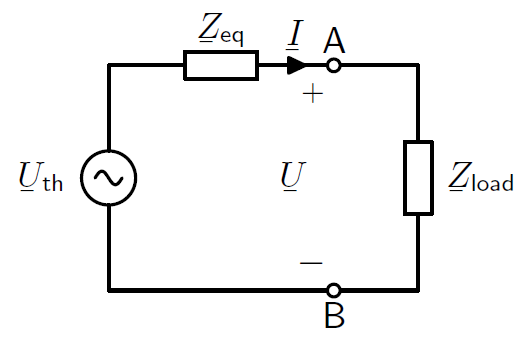

Uth could also be found in the literature as E

Zeq could also be found in the literature as Zth

Next, the impedances of the circuit are defined:

- Load impedance Zl

- Thevenin equivalent impedance Zth

- Definition in polar format

disp('Impedances definition: Module/angle/phasor')

Impedances definition: Module/angle/phasor


Zml=3                          % Module (load)

Zml = 3

Zal=30                         % Angle (load)

Zal = 30

Zl=Zml*exp(1i*Zal*pi/180)      % Phasor (load)

Zl = 2.5981 + 1.5000i

Zmth=3                         % Module (Thevenin equivalent)

Zmth = 3

Zath=45                        % Angle (Thevenin equivalent)

Zath = 45

Zth=Zmth*exp(1i*Zath*pi/180)   % Phasor (Thevenin equivalent)

Zth = 2.1213 + 2.1213i

Definition of the voltage Uth (E)

disp('Voltage definition: Module/angle/phasor')

Voltage definition: Module/angle/phasor


Umth=8                                              % Voltage (module)

Umth = 8

Uath=0                  % Voltage (angle)

Uath = 0

Uth=Umth*exp(1i*Uath*pi/180)                        % Voltage (phasor) 

Uth = 8

Current calculation

disp('Circuit current I')

Circuit current I


I=Uth/(Zl+Zth)          % Calculation of the current

I = 1.0669 - 0.8187i

Im=abs(I)               % Current module

Im = 1.3448

Ia=angle(I)             % Current angle

Ia = -0.6545

Iadeg=Ia*180/pi         % Current angle deg

Iadeg = -37.5000

Load voltage calculation (Ul or U)

disp('Load voltage')

Load voltage


Ul=I*Zl                 % Load voltage

Ul = 4.0000 - 0.5266i

Uml=abs(Ul)             % Load voltage module

Uml = 4.0345

Ual=angle(Ul)           % Load voltage angle

Ual = -0.1309

Ualdeg=angle(Ul)*180/pi % Load voltage angle

Ualdeg = -7.5000

Load angle calculation

disp('Load angle calculation based on impedance expression')

Load angle calculation based on impedance expression


phi1=angle(Zl)          % Load angle

phi1 = 0.5236

disp('Load angle calculation based on load voltage and current division - load angle')

Load angle calculation based on load voltage and current division - load angle


phi1bis=angle(Ul/I)     % Load angle (from load voltage and current)

phi1bis = 0.5236

disp('Load angle calculation based on voltage and currrent angle difference')

Load angle calculation based on voltage and currrent angle difference


phi2=angle(Ul)         % Load voltage angle

phi2 = -0.1309

phi3=angle(I)          % Current angle

phi3 = -0.6545

phi1bisbis=angle(Ul)-angle(I)

phi1bisbis = 0.5236

%phi1deg=phi1*180/pi


Cosfi calculation (power factor) based on previous angles

disp('cosphi based on load angle')

cosphi based on load angle


cosphi1=cos(angle(Zl))  % Cosphi based on load angle

cosphi1 = 0.8660

disp('cosfi calculation based on load voltage and current division - load angle')

cosfi calculation based on load voltage and current division - load angle


cosphi1=cos(angle(Ul/I))  % Cosphi based on load angle

cosphi1 = 0.8660

disp('cosphi calculation based on voltage and currrent angle difference')

cosphi calculation based on voltage and currrent angle difference


cosphi2=cos(angle(Ul)-angle(I)) 

cosphi2 = 0.8660

% cosphi based on difference between load voltage and current

Power calculation based on different methods

disp('Complex power calculation')

Complex power calculation


S=Ul*conj(I)            % Complex power calculation

S = 4.6989 + 2.7129i

S1=abs(Ul)^2/conj(Zl)   % Calculation complex power method 2

S1 = 4.6989 + 2.7129i

S2=abs(I)^2*Zl          % Calculation complex power method 3

S2 = 4.6989 + 2.7129i

disp('Active power and reactive power calculation based on complex power')

Active power and reactive power calculation based on complex power


P1=real(S)              % Active power

P1 = 4.6989

Q1=imag(S)              % Reactive power

Q1 = 2.7129

disp('Active power and reactive power calculation based on power diagram')

Active power and reactive power calculation based on power diagram


P2=abs(Ul)*abs(I)*cos(angle(Ul)-angle(I)) %Active power U*I*cosphi

P2 = 4.6989

Q2=abs(Ul)*abs(I)*sin(angle(Ul)-angle(I)) %Active power U*I*sinphi

Q2 = 2.7129

Graph to better show the results

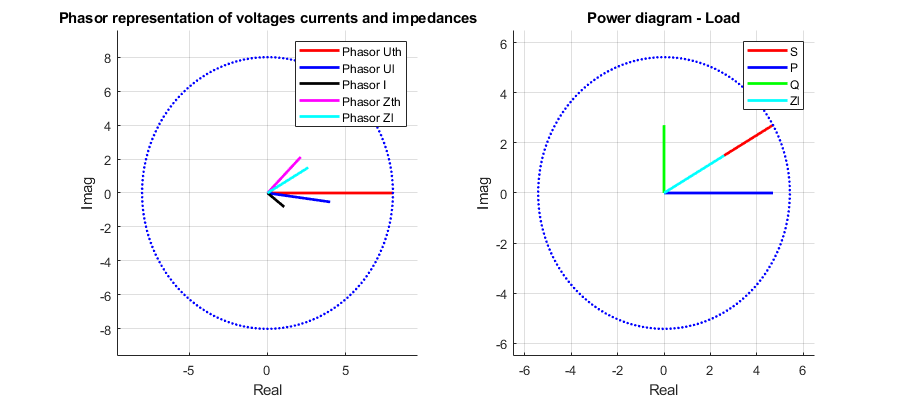

%% Combined plot of previous 4 graphs

figure('Position',[100 100 900 400])
subplot(121)
grid on
title('Phasor representation of voltages currents and impedances')
axis([-Umth*1.2,Umth*1.2 -Umth*1.2,Umth*1.2])
line([0,real(Uth)],[0,imag(Uth)],'Color','r','Linewidth',2)
hold all
line([0,real(Ul)],[0,imag(Ul)],'Color','b','Linewidth',2)
line([0,real(I)],[0,imag(I)],'Color','k','Linewidth',2)
line([0,real(Zth)],[0,imag(Zth)],'Color','m','Linewidth',2)
line([0,real(Zl)],[0,imag(Zl)],'Color','c','Linewidth',2)
t=0:0.0001:0.02;
circle=Umth*exp(1i*(2*pi*50*t));
plot(circle,'.','Color','b')
legend('Phasor Uth','Phasor Ul','Phasor I','Phasor Zth','Phasor Zl')
xlabel('Real')
ylabel('Imag')

subplot(122)
grid on
title('Power diagram - Load')
axis([-abs(S)*1.2,abs(S)*1.2,-abs(S)*1.2,abs(S)*1.2])
line([0,real(S)],[0,imag(S)],'Color','r','Linewidth',2)
hold all
line([0,real(S)],[0,0],'Color','b','Linewidth',2)
line([0,0],[0,imag(S)],'Color','g','Linewidth',2)
line([0,real(Zl)],[0,imag(Zl)],'Color','c','Linewidth',2)
circle=S*exp(1i*(2*pi*50*t));
plot(circle,'.','Color','b')
legend('S','P','Q','Zl')
xlabel('Real')
ylabel('Imag')